# **Hilbert Transform**

The Hilbert transform is an operation that shifts the phase of every frequency component in a signal by exactly **90°**, without changing the magnitude at any frequency.

In the frequency domain, the Hilbert Transform multiplies:  

- **+  **Positive frequencies by -j  (a -90 degree phase shift)

- **--  **Negative frequencies by +j  (a +90 degree phase shift)

**What it does to sinusoids:**

cos(w0*n)  -->  sin(w0*n)

**In MATLAB, the full analytic signal is computed in one line:**

x_a = hilbert(x);

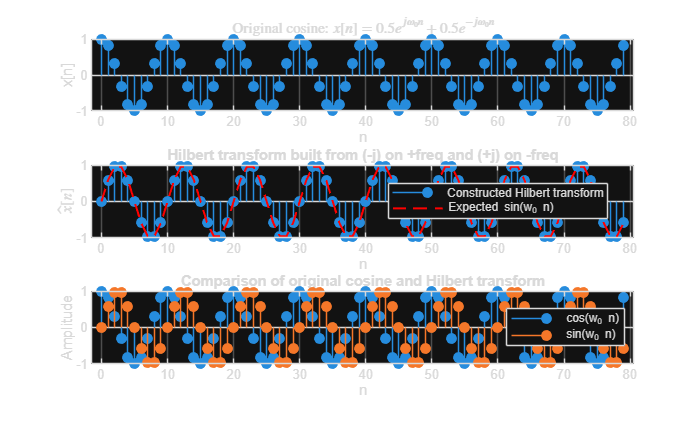

N  = 80;
n  = 0:N-1;
w0 = 0.2*pi;

x_pos = 0.5 * exp(1j*w0*n);         % positive component
x_neg = 0.5 * exp(-1j*w0*n);        % negative component
x = x_pos + x_neg;                  % cosine signal: x[n] = 0.5 e^{j w0 n} + 0.5 e^{-j w0 n} = cos(w0 n)

% Apply the Hilbert-transform rule in the frequency-domain sense:
% positive frequencies multiply by -j
% negative frequencies multiply by +j
xH_components = (-1j)*x_pos + (1j)*x_neg;

% The result should be a sine (ensure signal is real)
xH_real = real(xH_components);

% For comparison, the expected sine
xH_expected = sin(w0*n);

% Analytic signal formed from x + j*xH_components
xa = x + 1j*xH_components;

% Plot time-domain signals
figure('Color','w');

subplot(3,1,1);
stem(n, real(x), 'filled');
grid on;
xlabel('n');
ylabel('x[n]');
title('Original cosine: $x[n] = 0.5e^{j\omega_0 n} + 0.5e^{-j\omega_0 n}$', 'Interpreter','latex');

subplot(3,1,2);
stem(n, xH_real, 'filled'); hold on;
plot(n, xH_expected, 'r--', 'LineWidth', 1.2);
grid on;
xlabel('n');
ylabel('$\hat{x}[n]$','Interpreter','latex');
title('Hilbert transform built from (-j) on +freq and (+j) on -freq');
legend('Constructed Hilbert transform','Expected sin(w_0 n)','Location','best');

subplot(3,1,3);
stem(n, real(x), 'filled'); hold on;
stem(n, xH_real, 'filled');
grid on;
xlabel('n');
ylabel('Amplitude');
title('Comparison of original cosine and Hilbert transform');
legend('cos(w_0 n)','sin(w_0 n)','Location','best');

% The algebra numerically
disp(max(abs(xH_real - xH_expected)));

     0



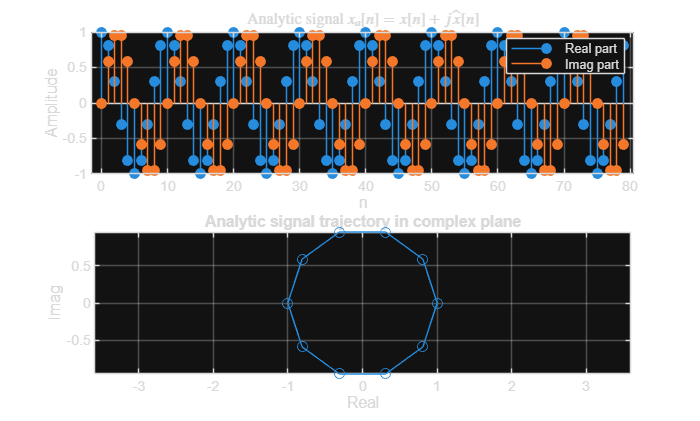

% x + j*xH leaves only the positive-frequency phasor
figure('Color','w');
subplot(2,1,1);
stem(n, real(xa), 'filled'); hold on;
stem(n, imag(xa), 'filled');
grid on;
xlabel('n');
ylabel('Amplitude');
title('Analytic signal $x_a[n] = x[n] + j\hat{x}[n]$', 'Interpreter', 'latex');
legend('Real part','Imag part','Location','best');

subplot(2,1,2);
plot(real(xa), imag(xa), 'o-');
axis equal; grid on;
xlabel('Real');
ylabel('Imag');
title('Analytic signal trajectory in complex plane');